# Extended Long-Run Incremental Cost Pricing for Distribution Networks Considering Stochastic Active and Reactive Power Injection

吴涵，南京工程学院智能电网产业技术研究院

Email: wuhanichina@gmail.com

clc, clear
addpath 'D:\OneDrive\Coding History\Matlab\Packages\matpower6.0'
addpath 'D:\OneDrive\Papers\08A probability approach of loss estimation\[Power Delivery]Medium Voltage Distribution Network’s Energy Loss Through Gaussian Mixture Model'

## 线性化潮流模型

$P_i =\sum_{j=1}^n G_{\textrm{ij}} V_j -\sum_{j=1}^n {B^{\prime } }_{\textrm{ij}} \theta_j$           (4)

$Q_i =-\sum_{j=1}^n B_{\textrm{ij}} V_j -\sum_{j=1}^n G_{\textrm{ij}} \theta_j$         (5)

$P_{\textrm{ij}} =g_{\textrm{ij}} \left(V_i -V_j \right)-b_{\textrm{ij}} \left(\theta_i -\theta_j \right)$  (7)

矩阵形式为：

$\left\lbrack \begin{array}{c}
\mathit{\mathbf{P}}\\
\mathit{\mathbf{Q}}
\end{array}\right\rbrack =-\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{B}}}^{\prime }  & -\mathit{\mathbf{G}}\\
\mathit{\mathbf{G}} & \mathit{\mathbf{B}}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta \\
\mathit{\mathbf{V}}
\end{array}\right\rbrack$              (8)

为方便计算，给出具体平衡节点r，PQ节点l、PV节点s的节点电压形式

$\left\lbrack \begin{array}{c}
\overset{~}{\mathit{\mathbf{P}}} \\
\overset{~}{\mathit{\mathbf{Q}}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
P_s \\
P_l \\
Q_l 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
{B^{\prime } }_{\textrm{sr}}  & -G_{\textrm{sr}}  & -G_{\textrm{ss}} \\
{B^{\prime } }_{\textrm{lr}}  & -G_{\textrm{lr}}  & -G_{\textrm{ls}} \\
G_{\textrm{lr}}  & B_{\textrm{lr}}  & B_{\textrm{ls}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta_r \\
{\mathit{\mathbf{V}}}_r \\
{\mathit{\mathbf{V}}}_s 
\end{array}\right\rbrack$           (12)

$\left\lbrack \begin{array}{cc}
H & N\\
M & L
\end{array}\right\rbrack =-\left\lbrack \begin{array}{ccc}
{B^{\prime } }_{\textrm{ss}}  & {B^{\prime } }_{\textrm{sl}}  & {-G}_{\textrm{sl}} \\
{B^{\prime } }_{\textrm{ls}}  & {B^{\prime } }_{\textrm{ll}}  & {-G}_{\textrm{ll}} \\
G_{\textrm{ls}}  & G_{\textrm{ll}}  & B_{\textrm{ll}} 
\end{array}\right\rbrack$                      (13)


$$\overset{~}{\theta} ={\left\lbrack \theta_s^T ,\theta_l^T \right\rbrack }^T$$


$\overset{~}{\mathit{\mathbf{V}}} =V_l$                                     (14)

$\overset{~}{\theta} ={\overset{~}{\mathit{\mathbf{H}}} }^{-1} \overset{~}{\mathit{\mathbf{P}}} -{\overset{~}{\mathit{\mathbf{H}}} }^{-1} \mathit{\mathbf{N}}{\mathit{\mathbf{L}}}^{-1} \overset{~}{\mathit{\mathbf{Q}}}$       (20)

$\overset{~}{\mathit{\mathbf{V}}} ={\overset{~}{\mathit{\mathbf{L}}} }^{-1} \overset{~}{\mathit{\mathbf{Q}}} -{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} \overset{~}{\mathit{\mathbf{P}}}$       (21)

节点电压的尾部分布


$$V_i ={\overset{~}{\mathit{\mathbf{L}}} }^{-1} \overset{~}{\mathit{\mathbf{Q}}} -{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} \overset{~}{\mathit{\mathbf{P}}} ={\overset{~}{\mathit{\mathbf{L}}} }^{-1} Q_i -{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} P_i$$


认为我们只有PQ节点，这样$\overset{~}{\mathit{\mathbf{P}}} =P_l +R_p$,$\overset{~}{\mathit{\mathbf{Q}}} =Q_l +R_q$


$$\begin{array}{l}
V={\overset{~}{\mathit{\mathbf{L}}} }^{-1} \overset{~}{\mathit{\mathbf{Q}}} -{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} \overset{~}{\mathit{\mathbf{P}}} \\
={\overset{~}{\mathit{\mathbf{L}}} }^{-1} \left(Q_l +R_q \right)-{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} \left(P_l +R_p \right)\\
={\overset{~}{\mathit{\mathbf{L}}} }^{-1} Q_l -{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} P_l +{\overset{~}{\mathit{\mathbf{L}}} }^{-1} R_q -{\overset{~}{\mathit{\mathbf{L}}} }^{-1} \mathit{\mathbf{M}}{\mathit{\mathbf{H}}}^{-1} R_p \\
=AQ_l +BP_l +C
\end{array}$$



$$V_i =\alpha_{\textrm{in}} Q_n +\beta_{\textrm{in}} P_n +c_{\textrm{in}}$$



$$\begin{array}{l}
I_{\textrm{ij}} =g_{\textrm{ij}} \left(V_i -V_j \right)\\
=g_{\textrm{ij}} \left(\alpha_{\textrm{in}} Q_n +\beta_{\textrm{in}} P_n +c_{\textrm{in}} -\alpha_{\textrm{jn}} Q_n -\beta_{\textrm{jn}} P_n -c_{\textrm{jn}} \right)\\
=\left(g_{\textrm{ij}} \alpha_{\textrm{in}} -g_{\textrm{ij}} \alpha_{\textrm{jn}} \right)Q_n +\left(g_{\textrm{ij}} \beta_{\textrm{in}} -g_{\textrm{ij}} \beta_{\textrm{jn}} \right)P_n +g_{\textrm{ij}} \left(c_{\textrm{in}} -c_{\textrm{jn}} \right)\\
=D_{\textrm{ijn}} Q_n +E_{\textrm{ijn}} P_n +F_{\textrm{ijn}} 
\end{array}$$


很显然，线性化之后的节点电压和相角可以分为有功和无功两个部分。

我们可以考虑针对电压和线路电流定价，但是有功和无功的和怎么办？

有功和无功的极值相依性应该很强，也就是说完全可以在定价时引入恒定的节点功率因素作为辅助值

## GPD的基本参数和性质

GPD的PDF：


$$f\left(x|\mu ,\sigma ,\xi \right)=\left(\frac{1}{\sigma }\right){\left(1+\mu \frac{\left(x-\xi \right)}{\sigma }\right)}^{-1-\frac{1}{\mu }}$$


CDF：


$$F\left(x|\mu ,\sigma ,\xi \right)=1-{\left(1+\frac{\left(x-\mu \right)}{\sigma }\right)}^{-\frac{1}{\xi }}$$


均值：


$$\mu +\frac{\sigma }{1-\xi }$$


GPD的两个性质

**1. 仿射封闭性**

对于*x*~*G*(*μ*,*σ*,* ξ*)，若*y* = *ax*+*b*，那么，*y *~ *G*(*aμ*+*b*,a*σ*,* ξ*)

**2. 阈值稳定性**

对于*x*~*G*(*μ*,*σ*,* ξ*)，若*y *=* x*−c`，`其中*c*是一个常数且*c* > *μ*，那么，*y *~ *G*(c,* σ*+*ξ*(c−*μ*),*ξ*)

结合上述两个性质，我们开始推导。

## 扩展的长期增量成本法 ELRIC

假设节点注入功率随机变量为$P_i$，其尾部概率分布服从GPD，即$P_i \sim G\left(x|\mu_i ,\sigma_i ,\xi_i \right)$

假设其他节点注入功率为定值，我们利用PTDF可将上述节点注入功率转化成线路功率$P_l$

$P_j \approx a_i P_i +\beta_i$, 其中为$\kappa_i$和$\beta_i$的PTDF系数


$$P_j \sim G\left(x|a_i \mu_i +\beta_i ,a_i \sigma_i ,\xi_i \right)$$


如果节点注入功率以r的年增率增长，由仿射封闭性可知，n年后的线路注入功率$P_l^n$也将增长


$$P_j^n =\left(a_{\textrm{ij}} {{\left(1+r\right)}^n P}_i +\beta_i \right)\sim G\left(x|{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i +\beta_i ,a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n ,\xi_i \right)$$


假设线路`l`的容量为$C_l^{\max }$，当$P_l^n \ge C_l^{\max }$即为线路容量越限。那么根据阈值稳定性，我们把他从$C_l^{\max }$截断后，依然可以得到一个新的GPD

$\Gamma_{j,n} =P_j^n \ge C_j^{\max } \sim G\left(C_j^{\max } ,a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i -\beta_i \right),\xi_i \right)$，这就是线路容量越上限的概率分布，即超出量的概率分布。

对于传统的LRIC方法，一旦出现线路容量越限即触发线路投资。但实际上，由于现代电网的发展，越来越多的调度方法可以用来降低线路功率，延缓投资。

于是我们换用更加经济性的方法，通过计算超出量的风险价值来判断是否出发投资。显然，这会使得ELRIC方法计算得到的电价低于传统的LRIC。

设假设每治理1MW功率的成本为$\eta$，那么超出量成本$\Gamma_{j,n}$的概率分布为：


$$G\left({\eta C}_j^{\max } ,\eta \left(a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i -\beta_i \right)\right),\xi_i \right)$$


其均值为：


$$E\left(\eta \Gamma_{j,n} \right)={\eta C}_j^{\max } +\frac{\eta \left(a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i -\beta_i \right)\right)}{1-\xi_i }$$


这个均值就是投资成本的条件风险价值CVaR。

那么反过来，我们来推一推ELRIC

假设未来的投资成本为${\textrm{Asset}}_l$,折旧率为`d`，那么净现值${\textrm{PV}}_l$为


$${\textrm{PV}}_j =\frac{{\textrm{Asset}}_j }{{\left(1+d\right)}^n }$$


当CVaR等于设备投资成本净现值时，我们触发投资，即


$$\begin{array}{l}
E\left(\eta \Gamma_{j,n} \right)={\textrm{PV}}_j \\
{\eta C}_j^{\max } +\frac{\eta \left(a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i -\beta_i \right)\right)}{1-\xi_i }=\frac{{\textrm{Asset}}_j }{{\left(1+d\right)}^n }
\end{array}$$


调整一下上式，我们有：


$$\begin{array}{l}
{\eta C}_j^{\max } +\frac{\eta \left(a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i -\beta_i \right)\right)}{1-\xi_i }=\frac{{\textrm{Asset}}_j }{{\left(1+d\right)}^n }\\
{{\eta C}_j^{\max } \left(1-\xi_i \right)\left(1+d\right)}^n +\eta {\left(1+d\right)}^n \left(a_{\textrm{ij}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n a_{\textrm{ij}} \mu_i -\beta_i \right)\right)={\left(1-\xi_i \right)\textrm{Asset}}_j 
\end{array}$$


上式是个超越方程，只能数值求解，但我们暂时不管他。

假设节点i有个$\Delta P_i$的功率注入，那么此时的线路功率有：


$$P_j^{\textrm{new}} \approx a_{\textrm{ij}} \left(P_i +\Delta P_i \right)+\beta_i$$



$$P_j^{\textrm{new}} \sim G\left(a_{\textrm{ij}} \mu_i +a_{\textrm{ij}} \Delta P_i +\beta_i ,a_{\textrm{ij}} \sigma_i ,\xi_i \right)$$



$$P_j^{n_{\textrm{new}} } =\left(a_{\textrm{ij}} {\left(1+r\right)}^{n_{\textrm{new}} } \left(P_i +\Delta P_i \right)+\beta_i \right)\sim G\left({\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \mu_i +{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \Delta P_i +\beta_i ,{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \sigma_i ,\xi_i \right)$$



$$\Gamma_{j,n_{\textrm{new}} } =P_j^{n_{\textrm{new}} } -C_j^{\max } \sim G\left(C_j^{\max } ,{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \sigma_i +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \mu_i -{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \Delta P_i -\beta_i \right),\xi_i \right)$$



$$E\left(\eta \Gamma_{j,n_{\textrm{new}} } \right)=\eta C_j^{\max } +\frac{\eta \left({\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \sigma_i +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \mu_i -{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \Delta P_i -\beta_i \right)\right)}{1-\xi_i }$$


同样在CVaR等于投资成本净现值的时候触发投资


$$\begin{array}{l}
E\left(\eta \Gamma_{j,n_{\textrm{new}} } \right)={\textrm{PV}}_j^{n_{\textrm{new}} } \\
\eta C_j^{\max } +\frac{\eta \left({\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \sigma_i +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \mu_i -{\left(1+r\right)}^{n_{\textrm{new}} } a_{\textrm{ij}} \Delta P_i -\beta_i \right)\right)}{1-\xi_i }=\frac{{\textrm{Asset}}_j }{{\left(1+d\right)}^{n_{\textrm{new}} } }
\end{array}$$


再回到新的净现值${\textrm{PV}}_l^{\textrm{new}}$


$${\textrm{PV}}_l^{\textrm{new}} =\frac{{\textrm{Asset}}_l }{{\left(1+d\right)}^{n_{\textrm{new}} } }$$


两个净现值相减就是注入功率后的成本增量


$${\Delta \textrm{PV}}_l ={\textrm{PV}}_l^{\textrm{new}} -{\textrm{PV}}_l$$


再算上年金因子AF，得到年度增量成本${\textrm{IC}}_l$


$${\textrm{IC}}_l =\textrm{AF}\cdot {\Delta \textrm{PV}}_l$$


把该节点导致的所有线路投资增量加来，就是该节点对应的扩展长期增量成本ELRIC


$${\textrm{ELRIC}}_i =\frac{\sum_l {\textrm{IC}}_l }{\Delta P_i }$$


## 数据接入

### 负荷与发电数据

% 负荷和DRE数据来自南通
load Nantongdata.mat 
IndoneH = data(:,1); % 工业负荷
ResdataoneH = data(:,2); % 居民负荷
ComoneH = data(:,3);% 商业负荷
Soldata = data(:,4)/(max(data(:,4))); % 光伏
Winddata = data(:,5)/(max(data(:,5))); % 风电
cap_i = 10; % 风电光伏容量
V_max = 1.07; % 节点电压上限1.07 p.u.
V_min = 0.93; % 节点电压下限0.93 p.u.
Pij_max = 0.08; % 线路容量上限 5.03MW.
Pij_min = -0.05; % 线路容量下限 -5.03MW.
% POT是超阈值分布，要先设定阈值。这里以10%和90%分位点为例
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q_lo = 0.1;
q_up = 0.9;
q_lo_Ind = quantile(IndoneH,q_lo); % 取工业负荷数据下分位点
q_up_Ind = quantile(IndoneH,q_up); % 取上分位点
q_up_Res = quantile(ResdataoneH,q_up); % 取上分位点
q_up_Com = quantile(ComoneH,q_up); % 取上分位点
q_lo_Sol = quantile(Soldata,q_lo); % 取光伏数据下分位点
q_up_Sol = quantile(Soldata,q_up); % 取上分位点
q_lo_Win = quantile(Winddata,q_lo); % 取风电数据下分位点
q_up_Win = quantile(Winddata,q_up); % 取上分位点

y_up_Ind = IndoneH(IndoneH>q_up_Ind)-q_up_Ind;
y_up_Res = IndoneH(ResdataoneH>q_up_Res)-q_up_Res;
y_up_Com = IndoneH(ComoneH>q_up_Com)-q_up_Com;
y_up_Sol = Soldata(Soldata>q_up_Sol)-q_up_Sol;
y_lo_Sol = q_lo_Sol-Soldata(Soldata<q_lo_Sol);
y_up_Win = Winddata(Winddata>q_up_Win)-q_up_Win;
y_lo_Win = q_lo_Win-Winddata(Winddata<q_lo_Win);
% 下面拟合GPD参数
full_Ind_pd = paretotails(IndoneH,q_lo,q_up); % 完整的工业负荷概率模型
full_Res_pd = paretotails(ResdataoneH,q_lo,q_up);

full_Com_pd = paretotails(ComoneH,q_lo,q_up);

full_Sol_pd = paretotails(Soldata,q_lo,q_up);

full_Win_pd = paretotails(Winddata,q_lo,q_up);

% 节点注入功率的GPD
pd_Ind_up_k = full_Ind_pd.UpperParameters(1); pd_Ind_up_s = full_Ind_pd.UpperParameters(2);
pd_Ind_lo_k = full_Ind_pd.LowerParameters(1); pd_Ind_lo_s = full_Ind_pd.LowerParameters(2);
pd_Res_up_k = full_Res_pd.UpperParameters(1); pd_Res_up_s = full_Res_pd.UpperParameters(2);
pd_Res_lo_k = full_Res_pd.LowerParameters(1); pd_Res_lo_s = full_Res_pd.LowerParameters(2);
pd_Com_up_k = full_Com_pd.UpperParameters(1); pd_Com_up_s = full_Com_pd.UpperParameters(2);
pd_Com_lo_k = full_Com_pd.LowerParameters(1); pd_Com_lo_s = full_Com_pd.LowerParameters(2);
pd_Sol_up_k = full_Sol_pd.UpperParameters(1); pd_Sol_up_s = full_Sol_pd.UpperParameters(2);
pd_Sol_lo_k = full_Sol_pd.LowerParameters(1); pd_Sol_lo_s = full_Sol_pd.LowerParameters(2);
pd_Win_up_k = full_Win_pd.UpperParameters(1); pd_Win_up_s = full_Win_pd.UpperParameters(2);
pd_Win_lo_k = full_Win_pd.LowerParameters(1); pd_Win_lo_s = full_Win_pd.LowerParameters(2);

## 线性化潮流参数

% 从case59China节点中导入数据
PCC_Voltage = 1.0;
in_bus = 9;
[para_aij,para_beta,para_cij,para_delta,gamma_ij,tau_ij] = get_power_flow_parameters(case59China,in_bus,PCC_Voltage);
nbus = length(para_aij);
nline = length(gamma_ij);

% 用的是交流潮流
case59 = ext2int(case59China);
resbus = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18]; % 居民用户节点
combus = [26,27,28,29,30,31,32,33]; % 商业用户节点
indbus = [19,20,21,22,23,24,25]; % 工业用户节点
windbus = [4 16 22 30]; % 风电节点
solbus = [9 17 21 23]; % 光伏节点
busPload = zeros(length(ResdataoneH),nbus);
busQload = zeros(length(ResdataoneH),nbus);
lineloss = zeros(length(ResdataoneH),nline);
nodecurrent = zeros(length(ResdataoneH),nbus);
nodevoltage = zeros(length(ResdataoneH),nbus);
nodeang = zeros(length(ResdataoneH),nbus);
PF = zeros(length(ResdataoneH),nline);
PT = zeros(length(ResdataoneH),nline);
QF = zeros(length(ResdataoneH),nline);
QT = zeros(length(ResdataoneH),nline);

h = waitbar(0,"对原始数据执行牛拉法潮流计算");
for i=1:length(ResdataoneH)
    busPload(i,:) = case59.bus(:,3)'/10; % 对于其他节点，其负荷值恒定
    busQload(i,:) = case59.bus(:,4)'/10;

    % 对于随机负荷注入节点，需要调整其负荷为随机值
    busPload(i,intersect(resbus,in_bus)) = ResdataoneH(i);
    busPload(i,intersect(combus,in_bus)) = ComoneH(i);
    busPload(i,intersect(indbus,in_bus)) = IndoneH(i);
    busPload(i,intersect(windbus,in_bus)) = -ones(1,length(intersect(windbus,in_bus)))*Winddata(i);% 电源是负的
    busPload(i,intersect(solbus,in_bus)) = -ones(1,length(intersect(solbus,in_bus)))*Soldata(i)*cap_i;

    busQload(i,intersect(resbus,in_bus)) = ResdataoneH(i);
    busQload(i,intersect(combus,in_bus)) = ComoneH(i);
    busQload(i,intersect(indbus,in_bus)) = IndoneH(i);
    busQload(i,intersect(windbus,in_bus)) = -ones(1,length(intersect(windbus,in_bus)))*Winddata(i)*tan(acos(0.95));
    busQload(i,intersect(solbus,in_bus)) = -ones(1,length(intersect(solbus,in_bus)))*Soldata(i)*tan(acos(0.95))*cap_i;

    [lineloss(i,:),nodevoltage(i,:),nodeang(i,:),PF(i,:),PT(i,:),QF(i,:),QT(i,:)] = Compute_Energy_Loss('case59China',[busPload(i,:);busQload(i,:)]'); % 单位分别为W,A,p.u.
    waitbar(i/length(ResdataoneH));
end 


Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's 

close(h);

## 节点电压分布GPD计算


$$V_i =aP_i +b$$



$$V_i \sim G\left(y|a_{\textrm{ij}} \mu_i +\beta_j ,a_{\textrm{ij}} \sigma_i ,\xi_i \right)$$


V_GPD_up_para = zeros(nbus,3); % 节点电压GPD参数ξ,σ,μ
V_GPD_lo_para = zeros(nbus,3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 我们在这里对上面的数据作变换，要除以100，并且负荷要加个负号，发电则不用加负号
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for j=1:nbus
    V_GPD_up_para(j,1) = pd_Sol_up_k; % 形状参数k,ξ, tail index (shape) parameter k
    V_GPD_up_para(j,2) = para_aij(j)*pd_Sol_up_s/100*cap_i; % 尺度参数sigma, aσ,scale parameter sigma 除以10表示是10倍的光伏，光伏基准值是100kW
    V_GPD_up_para(j,3) = para_aij(j)*q_up_Sol/100*cap_i+para_beta(j); % 位置参数theta, au+b,threshold (location) parameter, theta,

    V_GPD_lo_para(j,1) = pd_Sol_lo_k; % 形状参数k,ξ, tail index (shape) parameter k
    V_GPD_lo_para(j,2) = para_aij(j)*pd_Sol_lo_s/100*cap_i; % 尺度参数sigma, aσ,scale parameter sigma 除以10表示是10倍的光伏，光伏基准值是100kW
    V_GPD_lo_para(j,3) = para_aij(j)*q_lo_Sol/100*cap_i+para_beta(j); % 位置参数theta, au+b,threshold (location) parameter, theta,
end

busVoltage = nodevoltage(:,in_bus);
x = linspace(0.93,1,100); % 上尾分布
y_GPD_Voltage_lo_pdf = gppdf(x,V_GPD_lo_para(in_bus,1),V_GPD_lo_para(in_bus,2),V_GPD_lo_para(in_bus,3));
y_GPD_Voltage_lo_cdf = gpcdf(x,V_GPD_lo_para(in_bus,1),V_GPD_lo_para(in_bus,2),V_GPD_lo_para(in_bus,3));


$$V_i \ge V_{\max } \sim G\left(y|V_{\max } ,a_{\textrm{ij}} \sigma_i +\xi_i \left(V_{\max } -a_{\textrm{ij}} \mu_i -\beta_j \right),\xi \right)$$


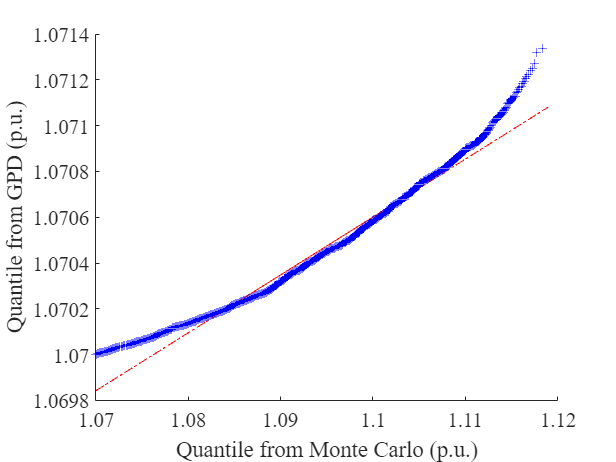

% 节点电压越限分布
V_GPD_MAX_para = zeros(nbus,3); % 节点电压GPD参数ξ,σ,μ
V_GPD_MIN_para = zeros(nbus,3);
for j=1:nbus
    V_GPD_MAX_para(j,1) = pd_Sol_up_k; % 形状参数k,ξ, tail index (shape) parameter k
    V_GPD_MAX_para(j,2) = para_aij(j)*pd_Sol_up_s/100*cap_i+pd_Sol_up_k*(V_max-para_aij(j)*q_up_Sol/100*cap_i-para_beta(j)); % 尺度参数sigma, aσ+ξ(Vmax-aμ-b),scale parameter sigma
    V_GPD_MAX_para(j,3) = V_max; % 位置参数theta, Vmax,threshold (location) parameter, theta,

    V_GPD_MIN_para(j,1) = pd_Sol_lo_k; % 形状参数k,ξ, tail index (shape) parameter k
    V_GPD_MIN_para(j,2) = para_aij(j)*pd_Sol_lo_s/100*cap_i+pd_Sol_lo_k*(para_aij(j)*q_lo_Sol/100*cap_i+para_beta(j)-V_min); % 这个可能有问题
    V_GPD_MIN_para(j,3) = V_min; % 位置参数theta, Vmax,threshold (location) parameter, theta,
end

x = linspace(1.06,1.12,100);
qqplot(busVoltage(busVoltage>V_max),gprnd(V_GPD_MAX_para(in_bus,1),V_GPD_MAX_para(in_bus,2),V_GPD_MAX_para(in_bus,3),[1000,1]))
xlabel("Quantile from Monte Carlo (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Quantile from GPD (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off');

## 线路功率GPD计算


$$\begin{array}{l}
P_{\textrm{ij}} =g_{\textrm{ij}} \left(V_i -V_j \right)-b_{\textrm{ij}} \left(\theta_i -\theta_j \right)\\
=g_{\textrm{ij}} \left(a_{\textrm{li}} P_l +\beta_i -a_{\textrm{lj}} P_l -\beta_j \right)-b_{\textrm{ij}} \left(c_{\textrm{li}} P_l +\delta_i -c_{\textrm{lj}} P_l -\delta_j \right)\\
=\left(g_{\textrm{ij}} \left(a_{\textrm{li}} -a_{\textrm{lj}} \right)-b_{\textrm{ij}} \left(c_{\textrm{li}} -c_{\textrm{lj}} \right)\right)P_l +g_{\textrm{ij}} \left(\beta_i -\beta_j \right)-b_{\textrm{ij}} \left(\delta_i -\delta_j \right)\\
=\gamma_{\textrm{lij}} P_l +\tau_{\textrm{ij}} 
\end{array}$$



$$P_{\textrm{nl}} \sim G\left(\gamma_{\textrm{ni}} \mu_n +\tau_{\textrm{nij}} ,\gamma_{\textrm{nij}} \sigma_n ,\xi_n \right)$$


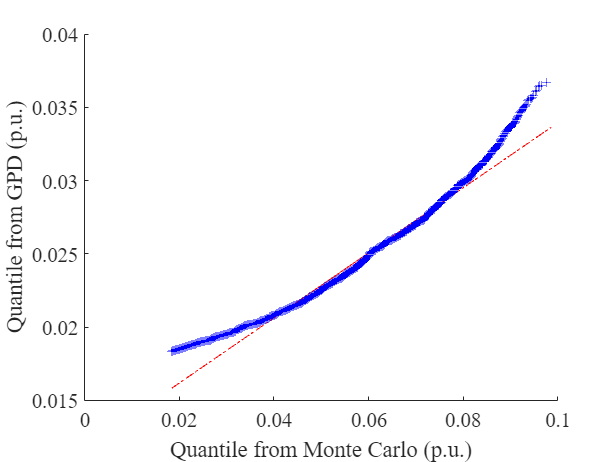

Line_GPD_up_para = zeros(nline,3); % 节点电压GPD参数ξ,σ,μ
Line_GPD_lo_para = zeros(nline,3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 我们在这里对上面的数据作变换，要除以100，并且负荷要加个负号，发电则不用加负号
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for l=1:nline
    Line_GPD_up_para(l,1) = pd_Sol_up_k; % 形状参数k,ξ, tail index (shape) parameter k
    Line_GPD_up_para(l,2) = gamma_ij(l)*pd_Sol_up_s/100*cap_i; % 尺度参数sigma, aσ,scale parameter sigma 除以10表示是10倍的光伏，光伏基准值是100kW
    Line_GPD_up_para(l,3) = gamma_ij(l)*q_up_Sol/100*cap_i+tau_ij(l); % 位置参数theta, au+b,threshold (location) parameter, theta,

    Line_GPD_lo_para(l,1) = pd_Sol_lo_k; % 形状参数k,ξ, tail index (shape) parameter k
    Line_GPD_lo_para(l,2) = gamma_ij(l)*pd_Sol_lo_s/100*cap_i; % 尺度参数sigma, aσ,scale parameter sigma 除以10表示是10倍的光伏，光伏基准值是100kW
    Line_GPD_lo_para(l,3) = gamma_ij(l)*q_lo_Sol/100*cap_i+tau_ij(l); % 位置参数theta, au+b,threshold (location) parameter, theta,
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 线路功率尾部概率分布，这里通过in_line来选择线路
in_line = 6; % 线路6
Line_P = PT(:,in_line)/100; % 注意这里我们用的标幺值
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qqplot(Line_P(Line_P>Line_GPD_lo_para(in_line,3)),gprnd(Line_GPD_lo_para(in_line,1),Line_GPD_lo_para(in_line,2),Line_GPD_lo_para(in_line,3),[1000,1]))
xlabel("Quantile from Monte Carlo (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Quantile from GPD (p.u.)",'FontSize',16,'Fontname', 'Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off');

$P_{\textrm{nl}} \ge P_{\max } \sim G\left(P_{\max } ,\gamma_{\textrm{nij}} \sigma_n ,+\xi_n \left(P_{\max } -\gamma_{\textrm{ni}} \mu_n -\tau_{\textrm{nij}} \right),\xi_n \right)$，线路功率越上限分布

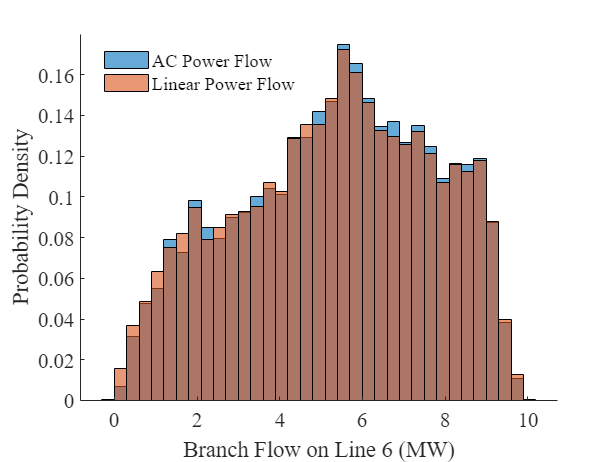

% 线路容量越限分布
Line_GPD_MAX_para = zeros(nline,3); % 节点电压GPD参数ξ,σ,μ
Line_GPD_MIN_para = zeros(nline,3);
for l=1:nline
    Line_GPD_MAX_para(l,1) = pd_Sol_up_k; % 形状参数k,ξ, tail index (shape) parameter k
    Line_GPD_MAX_para(l,2) = gamma_ij(l)*pd_Sol_up_s/100*cap_i+pd_Sol_up_k*(Pij_max-gamma_ij(l)*q_up_Sol/100*cap_i-tau_ij(l)); % 尺度参数sigma, aσ+ξ(Vmax-aμ-b),scale parameter sigma
    Line_GPD_MAX_para(l,3) = Pij_max; % 位置参数theta, Vmax,threshold (location) parameter, theta,

    Line_GPD_MIN_para(l,1) = pd_Sol_lo_k; % 形状参数k,ξ, tail index (shape) parameter k
    Line_GPD_MIN_para(l,2) = gamma_ij(l)*pd_Sol_lo_s/100*cap_i+pd_Sol_lo_k*(gamma_ij(l)*q_lo_Sol/100*cap_i+tau_ij(l)-Pij_min); % 这个可能有问题
    Line_GPD_MIN_para(l,3) = Pij_min; % 位置参数theta, Vmax,threshold (location) parameter, theta,
end

Line_POT_inj = zeros(length(IndoneH),nline);
for k=1:length(IndoneH)
    for l=1:nline % 这里的取值范围是所有线路
        Line_POT_inj(k,l) = (gamma_ij(l)*Soldata(k)/100*cap_i+tau_ij(l)); % 计算得到的线路电流
    end
end

[f,xi] = ksdensity(Line_POT_inj(:,6)); 
histogram(PT(:,6),'Normalization','pdf') % 注意这里我们用的标幺值
hold on 
histogram(Line_POT_inj(:,6)*100,'Normalization','pdf')
% plot(xi,f,'r-','LineWidth',2) %  对比AC交流潮流和线性化潮流电压计算结果
legend('AC Power Flow','Linear Power Flow','Location','best') % 拟合效果还行
legend('boxoff')
xlabel("Branch Flow on Line 6 (MW)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off');
hold off

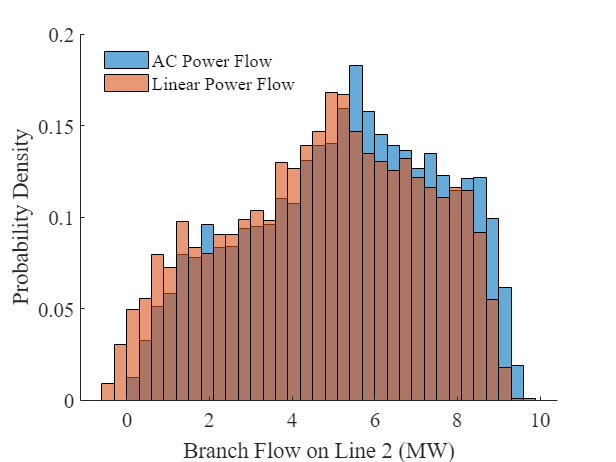

[f,xi] = ksdensity(Line_POT_inj(:,2)); 
histogram(PT(:,2),'Normalization','pdf') % 注意这里我们用的标幺值
hold on 
histogram(Line_POT_inj(:,2)*100,'Normalization','pdf')
% plot(xi,f,'r-','LineWidth',2) %  对比AC交流潮流和线性化潮流电压计算结果
legend('AC Power Flow','Linear Power Flow','Location','best') % 拟合效果还行
legend('boxoff')
xlabel("Branch Flow on Line 2 (MW)",'FontSize',16,'Fontname', 'Times New Roman')
ylabel("Probability Density",'FontSize',16,'Fontname', 'Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off');
hold off

## 经典LRIC方法计算（节点注入）


$$C^{\max } ={\left(1+r\right)}^m P^{\max }$$


delta_Pi = 0.1; % 节点注入功率增量
r = 0.03; % load growth rate负荷增长率
d = 0.069; % discount rate折现率
Asset = 3000000; % 设备成本
C_max = 10; % 线路容量 假定是10吧
eta = 1000; % 单位阻塞管理 ￥/MW
P_i = case59China().bus(:,3); % 节点负荷Pd 第三列
Q_i = case59China().bus(:,4); % 节点负荷Pd 第三列
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
n_LRIC_old = zeros(nline,nbus); % 旧的年限定义
PV_LRIC_old = zeros(nline,nbus); % 现值定义
AF_LRIC_old = zeros(nline,nbus); % 年金因子的定义
for i = 1:nbus % 每个节点注入一次功率计算LRIC
    [~,~,~,P_l,~,~,~] = Compute_Energy_Loss('case59China',[P_i';Q_i']'); % 单位分别为W,A,p.u.
    P_l = abs(P_l);
    for l=1:nline
        n_LRIC_old(l,i) = (log(C_max)-log(P_l(l)))/log(1+r); % 现有的年限
        PV_LRIC_old(l,i) = Asset/((1+d).^n_LRIC_old(l,i)); % 当前净现值
        AF_LRIC_old(l,i) = 1/r-1/(1+r)^n_LRIC_old(l,i); % 年金系数
    end
end


Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
n_LRIC_new = zeros(nline,nbus); % 新的年限定义
PV_LRIC_new = zeros(nline,nbus); % 现值定义
AF_LRIC = zeros(nline,nbus); % 年金系数定义
IC_LRIC = zeros(nline,nbus); % 增量成本定义
LRIC = zeros(nline,1); % 长期增量成本

for i = 1:nbus % 每个节点注入一次功率计算LRIC
    delta_p = zeros(nbus,1);
    delta_p(i) = 1;
    P_i_new = P_i + delta_p;
    Q_i_new = Q_i + delta_p*tan(0.95);
    [~,~,~,P_l_new,~,~,~] = Compute_Energy_Loss('case59China',[P_i_new';Q_i_new']'); % 单位分别为W,A,p.u.
    P_l_new = abs(P_l_new);
    for l = 1:length(P_l_new)
        n_LRIC_new(l,i) = (log(C_max)-log(P_l_new(l)))/log(1+r); % 节点i新增注入功率后的年限
        PV_LRIC_new(l,i) = Asset/((1+d).^n_LRIC_new(l,i)); % 节点i新增注入功率后的净现值
        AF_LRIC(l,i) = 1/r-1/(1+r)^n_LRIC_new(l,i); % 年金系数
        IC_LRIC(l,i) = (PV_LRIC_new(l,i)-PV_LRIC_old(l,i))*AF_LRIC(l,i); % 现值
    end
LRIC(i) = sum(IC_LRIC(:,i))/delta_Pi;
end


Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's 

## 扩展LRIC方法计算（节点注入）

% 下面开始计算ELRIC
eLRIC = zeros(nbus,1); % 扩展长期增量成本定义
n_eLRIC_old = zeros(nline,nbus); % 各条线路的初始投资年限
n_eLRIC_new = zeros(nline,nbus); % 节点i新增负荷各条线路的投资年限
PV_eLRIC_old = zeros(nline,nbus);% 节点i新增负荷前线路l投资的净现值
PV_eLRIC_new = zeros(nline,nbus);% 节点i新增负荷后线路l投资的净现值
AF_eLRIC = zeros(nline,1); % 年金系数定义
IC_eLRIC = zeros(nline,1); % 现值定义

gamma_ij_n = zeros(nline,1); % 节点i的系数
tau_ij_n = zeros(nline,1); % i节点需要加上的系数


$${\eta C}_j^{\max } +\frac{\eta \left(\gamma_{\textrm{ijn}} \sigma_i {\left(1+r\right)}^n +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^n \gamma_{\textrm{ijn}} \mu_i -\tau_{\textrm{ijn}} \right)\right)}{1-\xi_i }=\frac{{\textrm{Asset}}_j }{{\left(1+d\right)}^n }$$


for i = 1:nbus    
    % 第一步，计算n_old,即计算上面这个方程的解
     % 首先更新线性化潮流参数
     [~,~,~,~,gamma_ij_n,tau_ij_n] = get_power_flow_parameters(case59China,i,PCC_Voltage);

    for l=setdiff(1:nline,find(PT(1,:)==0)) % 线路14上没有功率。。。所以这里就略掉吧
        ELRIC_get_n = @(n)cvar_equal(n, d, C_max, Asset, eta, r, gamma_ij_n(l), tau_ij_n(l), q_up_Ind, pd_Ind_up_s, pd_Ind_up_k);
        interval = [1  200];
        n_eLRIC_old(l,i) = fzero(ELRIC_get_n,interval); % 求解ELRIC_get_n=0
        % 第二步，计算原始设备投资成本的净现值
        % 为了减少循环次数，就放在这里一起做了
        PV_eLRIC_old(l,i) = Asset/(1+d)^n_eLRIC_old(l,i);
    end


$$\eta C_j^{\max } +\frac{\eta \left({\left(1+r\right)}^{n_{\textrm{new}} } \gamma_{\textrm{ijn}} \sigma_i +\xi_i \left(C_j^{\max } -{\left(1+r\right)}^{n_{\textrm{new}} } \gamma_{\textrm{ijn}} \mu_i -{\left(1+r\right)}^{n_{\textrm{new}} } \gamma_{\textrm{ijn}} \Delta P_i -\tau_{\textrm{ijn}} \right)\right)}{1-\xi_i }=\frac{{\textrm{Asset}}_j }{{\left(1+d\right)}^{n_{\textrm{new}} } }$$


    % 第三步，计算节点新增负荷之后的年限和净现值，公式在上面
    for l=setdiff(1:nline,find(PT(1,:)==0)) % 线路14上没有功率。。。所以这里就略掉吧
        ELRIC_get_n = @(n)new_cvar_equal(n, delta_Pi,d, C_max, Asset, eta, r, gamma_ij_n(l), tau_ij_n(l), q_up_Ind, pd_Ind_up_s, pd_Ind_up_k);
        interval = [1  200];
        n_eLRIC_new(l,i) = fzero(ELRIC_get_n,interval); % 求解ELRIC_get_n=0
        % 第二步，计算原始设备投资成本的净现值
        % 为了减少循环次数，就放在这里一起做了
        PV_eLRIC_new(l,i) = Asset/((1+d)^n_eLRIC_new(l,i));
    end


$${\Delta \textrm{PV}}_l ={\textrm{PV}}_l^{\textrm{new}} -{\textrm{PV}}_l$$



$${\textrm{IC}}_l =\textrm{AF}\cdot {\Delta \textrm{PV}}_l$$


    % 第四步，计算净现值变化量、IC
    for l=setdiff(1:nline,find(PT(1,:)==0))
        AF_eLRIC(l) = 1/r-1/(1+r)^n_eLRIC_new(l,i); % 年金系数
        IC_eLRIC(l) = (PV_eLRIC_new(l,i)-PV_eLRIC_old(l,i))*AF_eLRIC(l); % 现值
    end
    % 第五步，计算扩展长期增量成本
    eLRIC(i) = sum(IC_eLRIC)/delta_Pi;
end

% 可以看出来我们的eLRIC是要比LRIC便宜不少的
delta_node_price = eLRIC-LRIC;

### 灵敏度分析

不同负荷和发电的ELRIC

% 负荷
[n_old_LRIC, n_new_LRIC, LRIC] = LRIC_Load_fun_Dis(case59China,r,d,Asset,C_max);


Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's 

[n_old_ELRIC_ind, n_new_ELRIC_ind, ELRIC_ind] = ELRIC_Load_fun_Dis(case59China,IndoneH,eta,r,d,Asset,C_max);
[n_old_ELRIC_res, n_new_ELRIC_res, ELRIC_res] = ELRIC_Load_fun_Dis(case59China,ResdataoneH,eta,r,d,Asset,C_max);

[n_old_ELRIC_com, n_new_ELRIC_com, ELRIC_com] = ELRIC_Load_fun_Dis(case59China,ComoneH,eta,r,d,Asset,C_max);

% 发电
[n_old_LRIC_Gen, n_new_LRIC_Gen, LRIC_Gen] = LRIC_Gen_fun_Dis(case59China,r,d,Asset,C_max);


Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's method power flow converged in 3 iterations.

Newton's 

[n_old_ELRIC_PV, n_new_ELRIC_PV, ELRIC_PV] = ELRIC_Gen_fun_Dis(case59China,Soldata,eta,r,d,Asset,C_max);

[n_old_ELRIC_Wind, n_new_ELRIC_Wind, ELRIC_Wind] = ELRIC_Gen_fun_Dis(case59China,Winddata,eta,r,d,Asset,C_max);

nelric = n_old_ELRIC_ind-n_new_ELRIC_ind;nlric= n_old_LRIC-n_new_LRIC;

 线路投资时间LRIC/ELRIC

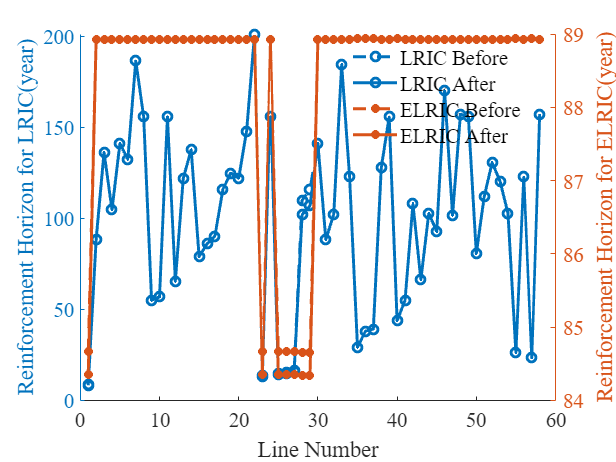

look_node = 30;
figure
plotline = 1:58;
yyaxis left
plot(plotline,n_old_LRIC(:,look_node),'--o', ...
     plotline,n_new_LRIC(:,look_node),'-o', 'LineWidth',2);
ylabel("Reinforcement Horizon for LRIC(year)",'FontSize',14,'Fontname','Times New Roman')
yyaxis right
plot(plotline,n_old_ELRIC_ind(:,look_node),'--*', ...
    plotline,n_new_ELRIC_ind(:,look_node),'-*', 'LineWidth',2);
legend('LRIC Before','LRIC After','ELRIC Before','ELRIC After','Location','best','FontSize',14,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Line Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Reinforcement Horizon for ELRIC(year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

线路净现值LRIC/ELRIC

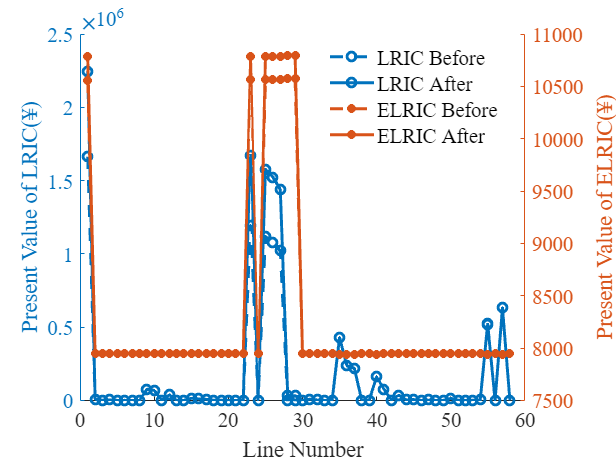

figure
yyaxis left
plot(plotline,PV_LRIC_old(:,look_node),'--o', ...
    plotline,PV_LRIC_new(:,look_node),'-o', 'LineWidth',2)
ylabel("Present Value of LRIC(¥)",'FontSize',14,'Fontname','Times New Roman')
yyaxis right
plot(plotline,PV_eLRIC_old(:,look_node),'--*', ...
    plotline,PV_eLRIC_new(:,look_node),'-*', 'LineWidth',2)
legend('LRIC Before','LRIC After','ELRIC Before','ELRIC After','Location','best','FontSize',14,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Line Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Present Value of ELRIC(¥)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

节点电价LRIC/ELRIC

% 节点电价ELRIC
plotbus = 2:59;
figure
yyaxis left
plot(plotbus,LRIC(plotbus),'--o', 'LineWidth',2)
ylabel("Network Charge of LRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
yyaxis right
plot(plotbus,ELRIC_ind(plotbus),'-o','LineWidth',2)
legend('LRIC','ELRIC Ind','ELRIC Res','ELRIC Com','Location','best','FontSize',14,'Fontname', 'Times New Roman')

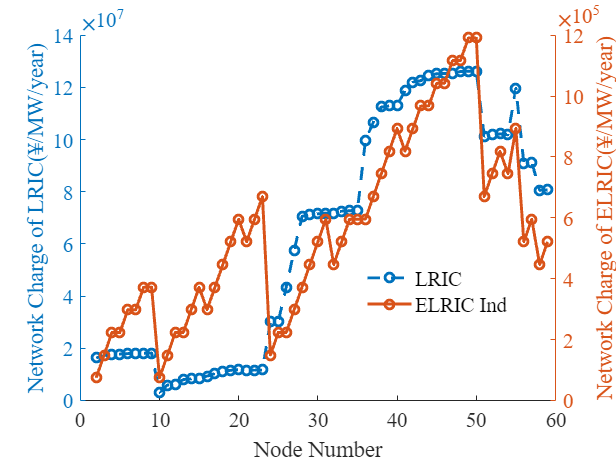

legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge of ELRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

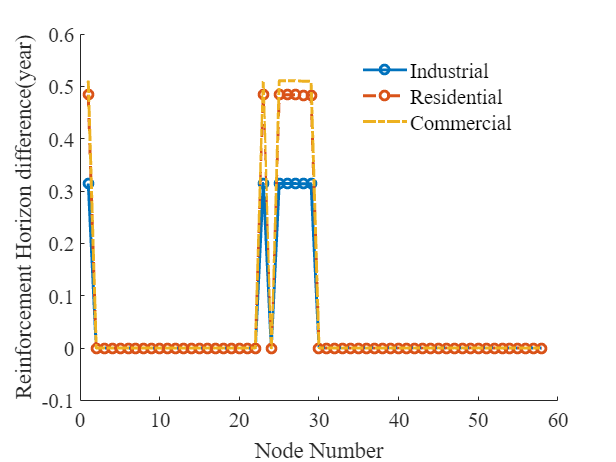

% 节点电价ELRIC
plotbus = 2:59;
% figure
% plot(plotline,n_old_ELRIC_ind(:,look_node),'-o', ...
%      plotline,n_new_ELRIC_ind(:,look_node),'-.o', ...
%      plotline,n_old_ELRIC_res(:,look_node),'-*',...
%      plotline,n_new_ELRIC_res(:,look_node),'-.*',...
%      plotline,n_old_ELRIC_com(:,look_node),'--',...
%      plotline,n_new_ELRIC_com(:,look_node),'--.','LineWidth',2)
% legend('Ind Before','Ind After','Res Before','Res After','Com Before','Com After',...
%       'Location','best','FontSize',14,'Fontname', 'Times New Roman')
% legend('boxoff')
% xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
% ylabel("Reinforcement Horizon for ELRIC(year)",'FontSize',14,'Fontname','Times New Roman')
% set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

figure
plot(plotline,n_old_ELRIC_ind(:,look_node)-n_new_ELRIC_ind(:,look_node),'-o', ...
     plotline,n_old_ELRIC_res(:,look_node)-n_new_ELRIC_res(:,look_node),'--o',...'
     plotline,n_old_ELRIC_com(:,look_node)-n_new_ELRIC_com(:,look_node),'-.',...
     'LineWidth',2)
legend('Industrial','Residential','Commercial',...
      'Location','best','FontSize',14,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Reinforcement Horizon difference(year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

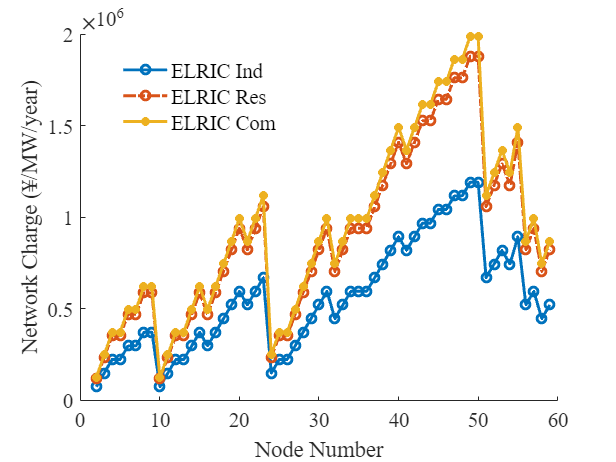

% 节点电价ELRIC
plotbus = 2:59;
figure
plot(plotbus,ELRIC_ind(plotbus),'-o', ...
    plotbus,ELRIC_res(plotbus),'-.o', ...
    plotbus,ELRIC_com(plotbus),'-*','LineWidth',2)
legend('ELRIC Ind','ELRIC Res','ELRIC Com','Location','best','FontSize',14,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge (¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

电源节点线路投资时间LRIC/ELRIC

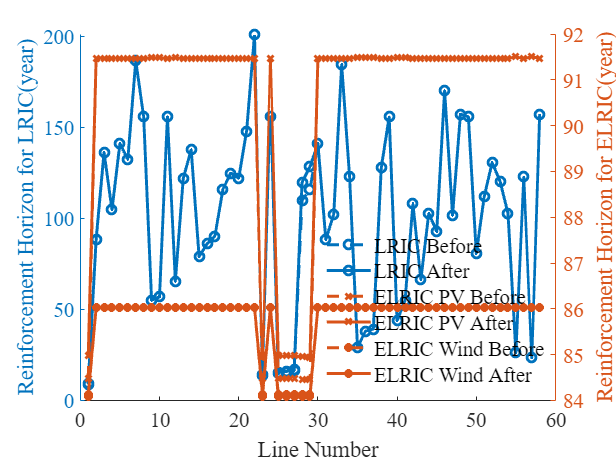

figure
yyaxis left
plot(plotline,n_old_LRIC_Gen(:,look_node),'--o', ...
    plotline,n_new_LRIC_Gen(:,look_node),'-o','LineWidth',2)
ylabel("Reinforcement Horizon for LRIC(year)",'FontSize',14,'Fontname','Times New Roman')
yyaxis right
plot(plotline,n_old_ELRIC_PV(:,look_node),'--x', ...
    plotline,n_new_ELRIC_PV(:,look_node),'-x', ...
    plotline,n_old_ELRIC_Wind(:,look_node),'--*', ...
    plotline,n_new_ELRIC_Wind(:,look_node),'-*','LineWidth',2)
legend('LRIC Before','LRIC After','ELRIC PV Before','ELRIC PV After',...
    'ELRIC Wind Before','ELRIC Wind After','Location','best','FontSize',14,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Line Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Reinforcement Horizon for ELRIC(year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

电源节点电价LRIC/ELRIC

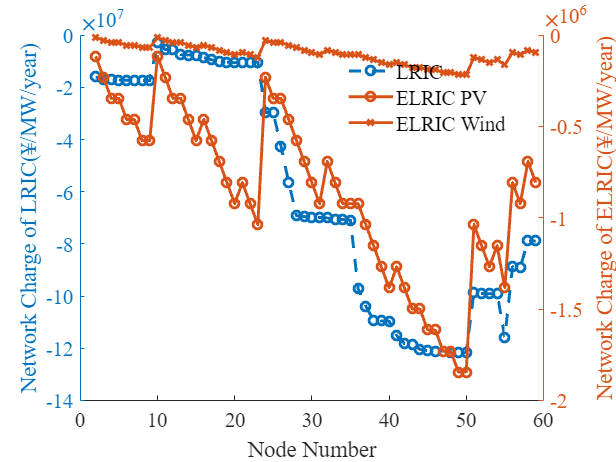

figure
yyaxis left
plot(plotbus,LRIC_Gen(plotbus),'--o','LineWidth',2)
ylabel("Network Charge of LRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
yyaxis right
plot(plotbus,ELRIC_PV(plotbus),'-o', ...
     plotbus,ELRIC_Wind(plotbus),'-x','LineWidth',2)
legend('LRIC','ELRIC PV','ELRIC Wind','Location','best','FontSize',14,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge of ELRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

#### 阻塞管理成本的影响

% 上分位点测试
q_up = 0.9:0.01:0.99;
ELRIC_q_test_dis = zeros(length(ELRIC_ind),length(q_up));
for i = 1:length(q_up)
    [~,~, ELRIC_q_test_dis(:,i)] = ELRIC_Load_Sensitivity_Test_Dis(case59China,q_up(i),IndoneH,eta,r,d,Asset,C_max);
end

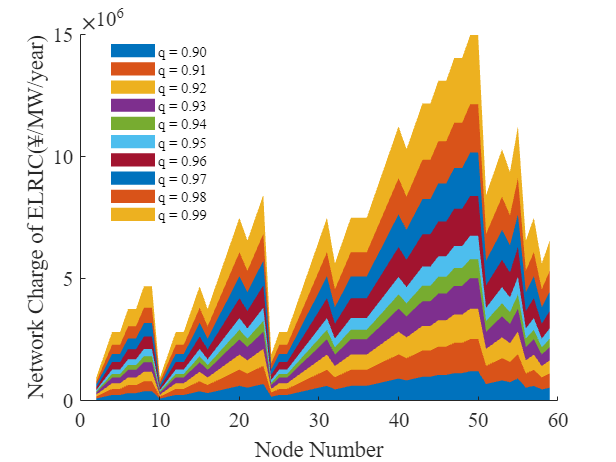

figure;
colormap("autumn")
a = area(plotbus,ELRIC_q_test_dis(plotbus,:));
for i = 1:length(a)
%    a(i).FaceColor = [0.01+(i-1)/length(plot_bus),0.01+(i-1)/length(plot_bus),0];
    a(i).EdgeColor = "none";
end
legend('q = 0.90','q = 0.91','q = 0.92','q = 0.93','q = 0.94','q = 0.95',...
    'q = 0.96','q = 0.97','q = 0.98','q = 0.99',...
    'Location','best','FontSize',10,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge of ELRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

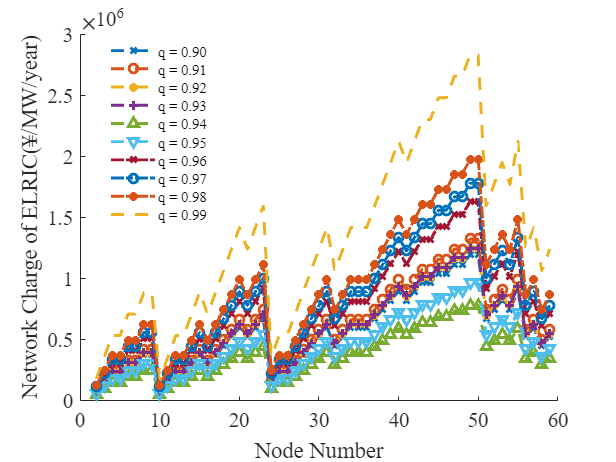

figure;
colormap("autumn")
plot(plotbus,ELRIC_q_test_dis(plotbus,1),'--x', ...
    plotbus,ELRIC_q_test_dis(plotbus,2),'--o', ...
    plotbus,ELRIC_q_test_dis(plotbus,3),'--*', ...
    plotbus,ELRIC_q_test_dis(plotbus,4),'--+',...
    plotbus,ELRIC_q_test_dis(plotbus,5),'--^',...
    plotbus,ELRIC_q_test_dis(plotbus,6),'--v',...
    plotbus,ELRIC_q_test_dis(plotbus,7),'-.x',...
    plotbus,ELRIC_q_test_dis(plotbus,8),'-.o',...
    plotbus,ELRIC_q_test_dis(plotbus,9),'-.*',...
    plotbus,ELRIC_q_test_dis(plotbus,10),'--','LineWidth',2)

legend('q = 0.90','q = 0.91','q = 0.92','q = 0.93','q = 0.94','q = 0.95',...
    'q = 0.96','q = 0.97','q = 0.98','q = 0.99',...
    'Location','best','FontSize',10,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge of ELRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

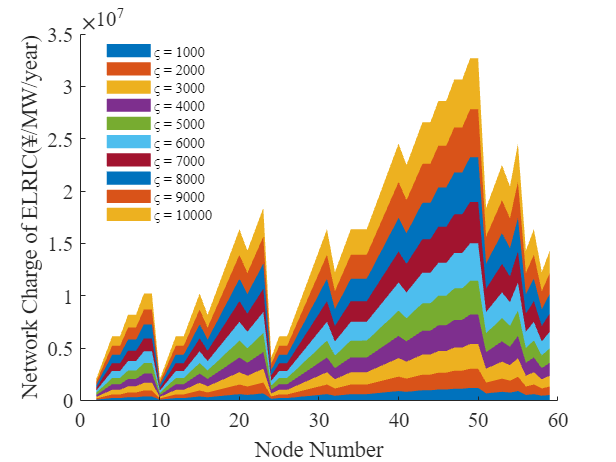

% 阻塞管理成本测试
eta = 1000:1000:10000;
ELRIC_ind_eta_dis = zeros(length(eta),length(LRIC));
for i = 1:length(eta)
    [~, ~, ELRIC_ind_eta_dis(i,:)] = ELRIC_Load_fun_Dis(case59China,IndoneH,eta(i),r,d,Asset,C_max);
end

figure;
b = area(plotbus,ELRIC_ind_eta_dis(:,plotbus)');
for i = 1:length(b)
%    b(i).FaceColor = [0.01+(i-1)/length(plot_bus),0.01+(i-1)/length(plot_bus),0];
    b(i).EdgeColor = "none";
end
legend('ς = 1000','ς = 2000','ς = 3000','ς = 4000','ς = 5000','ς = 6000',...
    'ς = 7000','ς = 8000','ς = 9000','ς = 10000',...
    'Location','best','FontSize',10,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge of ELRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')

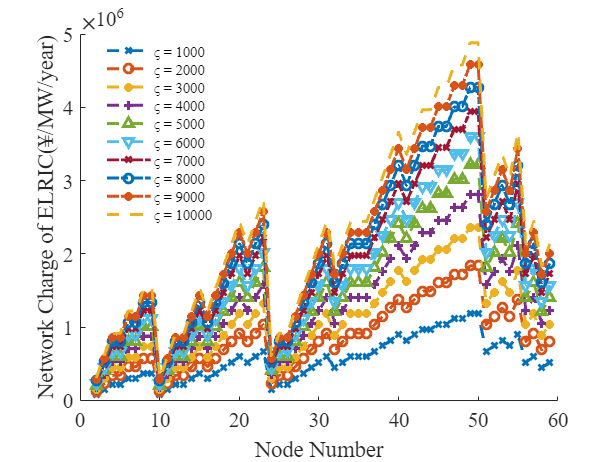

figure;
plot(plotbus,ELRIC_ind_eta_dis(1,plotbus),'--x', ...
    plotbus,ELRIC_ind_eta_dis(2,plotbus),'--o', ...
    plotbus,ELRIC_ind_eta_dis(3,plotbus),'--*', ...
    plotbus,ELRIC_ind_eta_dis(4,plotbus),'--+',...
    plotbus,ELRIC_ind_eta_dis(5,plotbus),'--^',...
    plotbus,ELRIC_ind_eta_dis(6,plotbus),'--v',...
    plotbus,ELRIC_ind_eta_dis(7,plotbus),'-.x',...
    plotbus,ELRIC_ind_eta_dis(8,plotbus),'-.o',...
    plotbus,ELRIC_ind_eta_dis(9,plotbus),'-.*',...
    plotbus,ELRIC_ind_eta_dis(10,plotbus),'--','LineWidth',2)
legend('ς = 1000','ς = 2000','ς = 3000','ς = 4000','ς = 5000','ς = 6000',...
    'ς = 7000','ς = 8000','ς = 9000','ς = 10000',...
    'Location','best','FontSize',10,'Fontname', 'Times New Roman')
legend('boxoff')
xlabel("Node Number",'FontSize',14,'Fontname','Times New Roman')
ylabel("Network Charge of ELRIC(¥/MW/year)",'FontSize',14,'Fontname','Times New Roman')
set(gca,'fontsize',14,'fontname','Times New Roman','box','off')